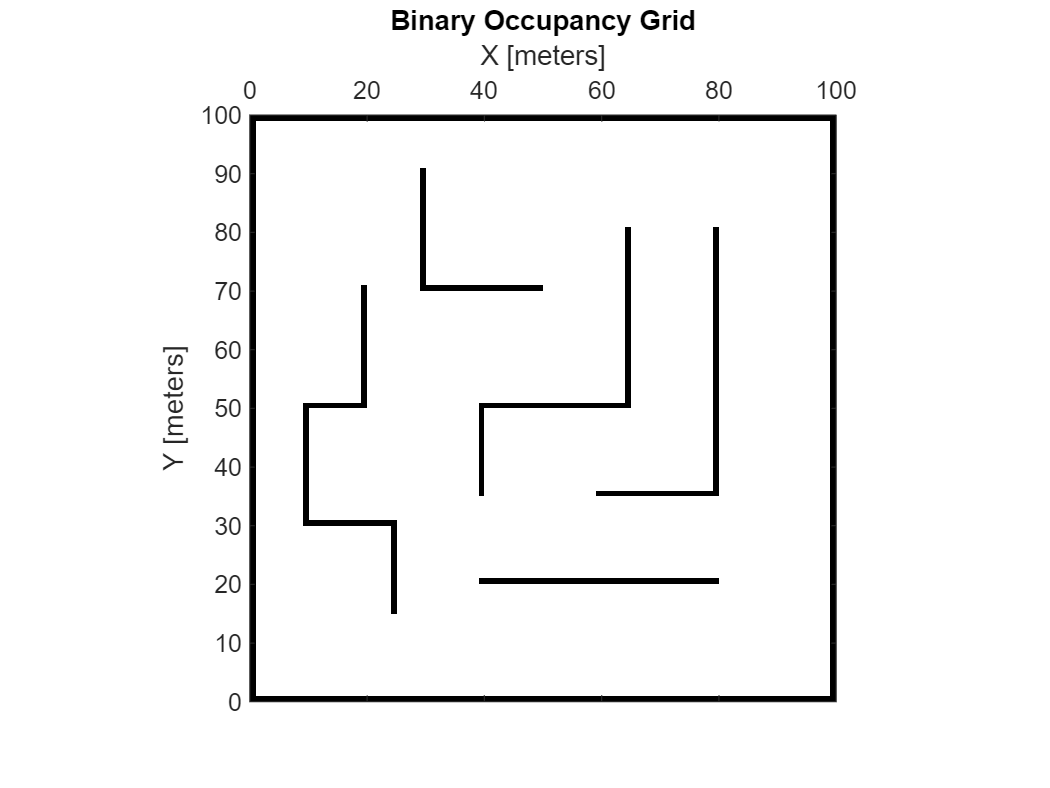

clear all;
clc;

xsize = 100; %[dm]
ysize = 100; %[dm]
resolution = 1;

%Create a map of 10 meters by 10 meters 
Ambient = binaryOccupancyMap(xsize,ysize,resolution);

%Create Numeric Array 
walls = zeros(xsize*resolution,ysize*resolution); %initialization
walls(1,1:end) = 1; %upper wall 
walls(xsize*resolution,1:end) = 1; %bottom wall
walls(1:end,1) = 1; %left wall
walls(1:end,ysize*resolution) = 1; %right wall

walls(10:30,30) = 1;
walls(30:50,20) = 1; 
walls(50:65,40) = 1;
walls(30,30:50) = 1;
walls(70,10:25) = 1;
walls(50:70,10) = 1;
walls(50,10:20) = 1;
walls(50,40:65) = 1; 
walls(70:85,25) = 1; 
walls(80,40:80) = 1; 
walls(65,60:80) = 1;
walls(20:65,80) = 1;
walls(20:50,65) = 1;


setOccupancy(Ambient, [1, 1], walls, "grid");
figure('Name', 'Ambient');
figure(1)
show(Ambient);
ax = gca;
ax.XAxisLocation = 'top';


occupation_matrix = zeros(xsize,ysize);
for i = 1:xsize
    for j = 1:ysize
        
        stato_occupazione = Ambient.getOccupancy([i, j]);
        
        if stato_occupazione == 1
            occupation_matrix(i,j) = 1;
        end
    end
end

correct_matrix = binaryOccupancyMap(rot90(occupation_matrix,1));

figure(2)
show(correct_matrix);
ambient_matrix = rot90(occupation_matrix,1);
ax = gca;
ax.XAxisLocation = 'top';



% Create the object location in the map
[n_rows, n_columns] = size(ambient_matrix);
cell_size = 3; % Each cell represents a brick in the space
k=1;
for i=1:n_rows
    for j=1:n_columns
        if ambient_matrix(i, j) == 1
            obstacles(k,:) = [j-cell_size/2, i-cell_size/2, cell_size, cell_size];
            k=k+1;
        end
    end
end

%% Test Lidar
lidar_position = [50, 40]; 
lidar_angles = linspace(0, 360, 100);  % 100 scanning lines
max_range = 20;
[out1,out2] = Lidar_scan(ambient_matrix, lidar_position, lidar_angles, max_range);

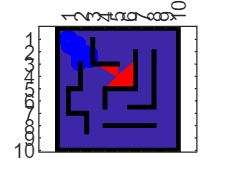

% Parametri di configurazione
space_limits = [0, xsize, 0, ysize]; % Dimensione dello spazio (x min, x max, y min, y max)

% Parametri dell'albero RRT
start = [10, 10];  % Punto di partenza
goal = [10* randn, 10* randn]; % Punto di arrivo
step_size = 0.5; % Lunghezza del passo per espandere l'albero in metri
max_iterations = 500; % Numero massimo di iterazioni
goal_threshold = 0.5; % Distanza minima per considerare il goal raggiunto


% Inizializzazione dell'albero RRT
rrt_tree = start; % L'albero inizia con il punto di partenza
parent_indices = 0; % Indice del genitore dell'albero RRT

% Creazione dell'albero RRT
for i = 1:max_iterations
    % Punto casuale nello spazio
    random_point = [rand() * xsize, rand() * ysize]; % Spazio limitato ai confini

    % Se il punto è negli ostacoli, scarta e continua
    if isInObstacle(random_point, obstacles)
        continue;
    end

    % Trova il punto più vicino nell'albero RRT
    distances = sqrt(sum((rrt_tree - random_point).^2, 2));
    [min_distance, nearest_idx] = min(distances);

    % Calcola il nuovo punto
    direction = random_point - rrt_tree(nearest_idx, :);
    unit_direction = direction / norm(direction);
    new_point = rrt_tree(nearest_idx, :) + step_size * unit_direction;

    % Controlla se il nuovo punto è dentro gli ostacoli
    if isInObstacle(new_point, obstacles)
        continue;
    end

    % Aggiungi il nuovo punto all'albero RRT
    rrt_tree = [rrt_tree; new_point];
    parent_indices = [parent_indices; nearest_idx];

    % Verifica se il punto è abbastanza vicino al goal
    if norm(new_point - goal) < goal_threshold
        disp('Goal raggiunto!');
        break;
    end
end

%Lidar Plot
figure(3)
imagesc(ambient_matrix);
%colormap('prism');
hold on;
ax = gca;
ax.XAxisLocation = 'top';
xticklabels(1:xsize/10);
yticklabels(1:ysize/10);
for angle_step = 1:length(lidar_angles)-1
    angle = lidar_angles(angle_step);
    ray_direction = [cosd(angle), sind(angle)];
    hit_point = out1(angle_step, :);
    if ~all(hit_point == 0) % Plot just hit points
        plot([lidar_position(1), hit_point(1)], [lidar_position(2), hit_point(2)], 'r-'); % Plot ray
    end
end

% Visualizzazione dell'albero RRT
figure(3)
plot(rrt_tree(:, 1), rrt_tree(:, 2), 'bo'); % Visualizza i punti
for i = 2:size(rrt_tree, 1)
    plot([rrt_tree(parent_indices(i), 1), rrt_tree(i, 1)], ...
         [rrt_tree(parent_indices(i), 2), rrt_tree(i, 2)], 'b-');
end
for i = 1:size(obstacles, 1)
    rectangle('Position', obstacles(i, :)); %'FaceColor', 'r','FaceAlpha', 0.5);
    set(gca, 'YDir', 'reverse');
    axis equal;
end
hold off

function is_inside = isInObstacle(point, obstacles)
    is_inside = false;
    for i = 1:size(obstacles, 1)
        obs = obstacles(i, :);
        if point(1) >= obs(1) && point(1) <= obs(1) + obs(3) && ...
           point(2) >= obs(2) && point(2) <= obs(2) + obs(4)
            is_inside = true;
            break;
        end
    end
end

%% 
function [obstacle_abs_coords,obstacle_abs_coords_clean] = Lidar_scan(ambient_matrix, lidar_position, lidar_angles, max_range)
    obstacle_abs_coords = zeros(length(lidar_angles), 2); 

    for angle_step = 1:length(lidar_angles)-1
        angle = lidar_angles(angle_step);
        ray_direction = [cosd(angle), sind(angle)];

        hit_point = [0,0]; 

        for range = 0:0.01:max_range
            scan_point = lidar_position + range * ray_direction;

            % Check if scanned point is inside map
            if scan_point(1) >= 1 && scan_point(1) <= size(ambient_matrix, 2) && ...
               scan_point(2) >= 1 && scan_point(2) <= size(ambient_matrix, 1)
                % Check if scanned poin is an obstacle
                if ambient_matrix(round(scan_point(2)), round(scan_point(1))) == 1
                    % Save absolute coordinates
                    hit_point = scan_point;
                    break;
                end
            else
                break;
            end
        end

        % Save absolute obstacle coordinates for each ray
        obstacle_abs_coords(angle_step, :) = hit_point;
    end
    %remove zeros from previous matrix
    index = any(obstacle_abs_coords ~= 0, 2);
    obstacle_abs_coords_clean= obstacle_abs_coords(index, :);

end

